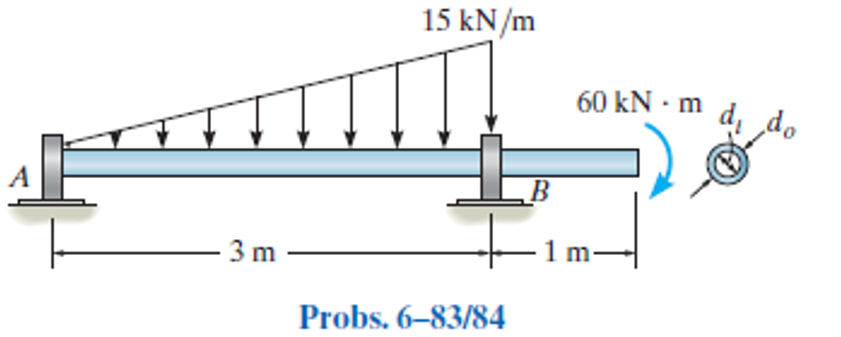

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-83P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-83P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 0], 'thru', [3*u.m -15*u.kN/u.m]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 3*u.m);
b = b.add('concentrated', 'moment', -60*u.kN*u.m, 4*u.m);
b = b.add('distributed', 'force', w1, [0 3]*u.m);
b.L = 4*u.m;

# section properties

Do = 200*u.mm;
Di = 160*u.mm;
b.I = rewrite(sympi*((Do/2)^4-(Di/2)^4)/4, u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{3125000\,x\,\left(x-3\,m\right)\,\left(x+3\,m\right)\,\left(x^{2}+59\,m^{2}\right)}{1107\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }x\leq 3\,m\\ -\frac{25000000\,\left(x-3\,m\right)\,\left(10\,x-13\,m\right)}{123\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{3}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3125000\,\left(5\,x^{4}+150\,x^{2}\,m^{2}-531\,m^{4}\right)}{1107\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }x\leq 3\,m\\ -\frac{25000000\,\left(20\,x-43\,m\right)}{123\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{3}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(x^{2}+15\,m^{2}\right)}{6}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ -60\,\mathrm{kN}\,m & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(x^{2}+5\,m^{2}\right)}{2}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ 0 & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -5\,x\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ 0 & \text{ if }3\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & -12.5\,\mathrm{kN}\\ \mathrm{Rb} & 35.0\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

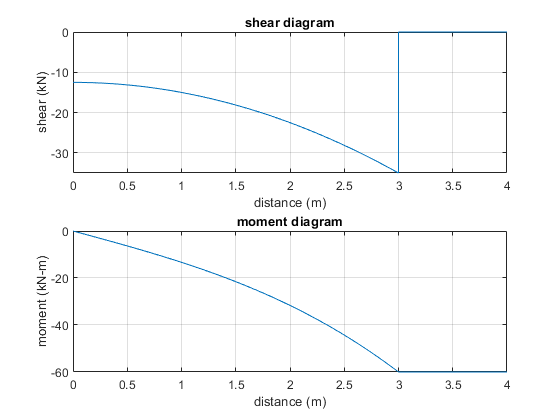

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# absolute maximum bending stress

M_max = -m(3*u.m)

$$M\_max = 60\,\mathrm{kN}\,m$$

C = Do/2;
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*C/b.I, u.MPa);
sigma_max_vpa = vpa(sigma_max, 5) %#ok<NASGU> 

$$sigma\_max\_vpa = 129.39\,\mathrm{MPa}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear sigma_max_vpa;